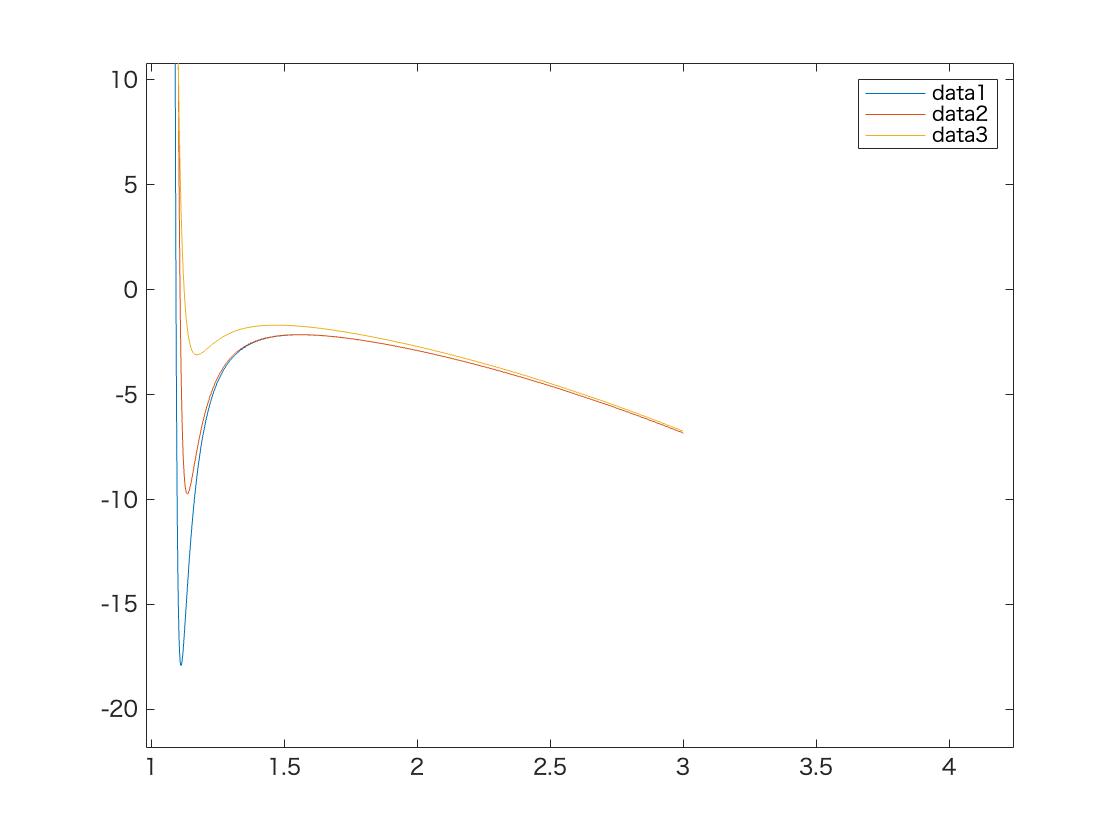

q=linspace(1,3,1000);
Z0=arrayfun(@(x)Inv(x,25),q);
Z1=arrayfun(@(x)Inv(x,15),q);
Z2=arrayfun(@(x)Inv(x,5),q);
figure
plot(q,[Z0;Z1;Z2])
ylim([-15 5])
legend

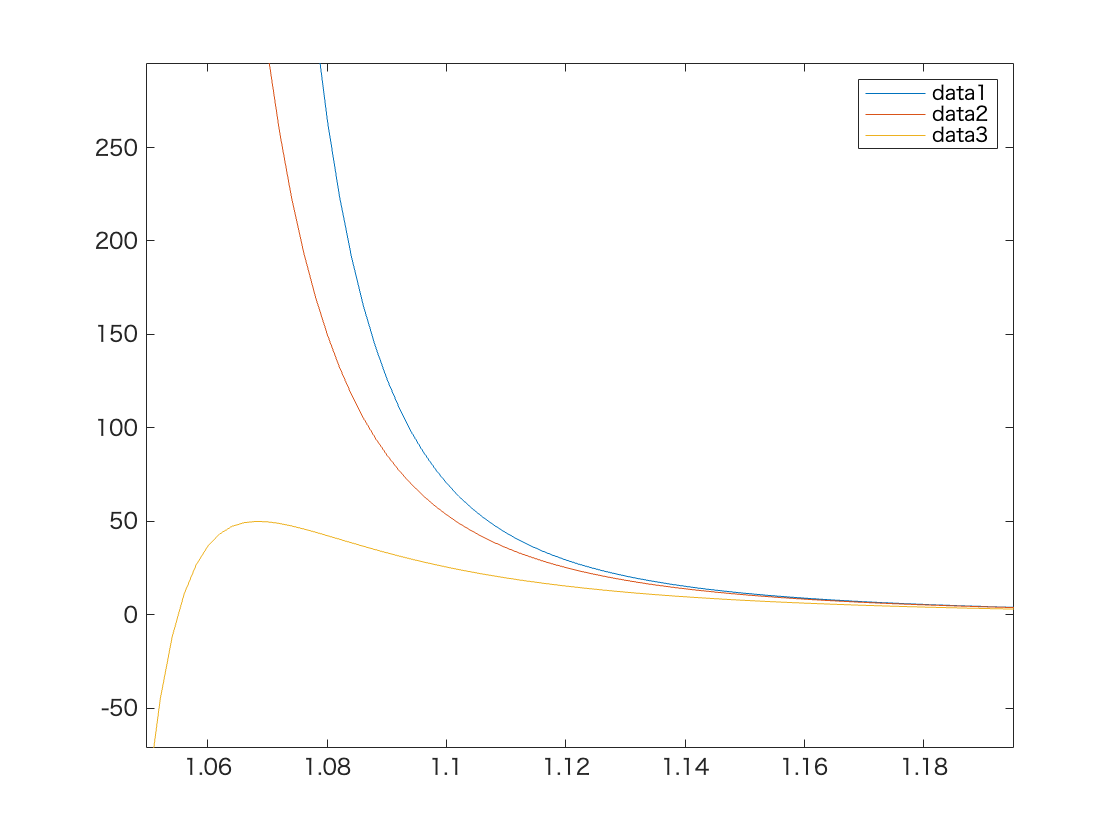


q=linspace(1,3,1000);
Z0=arrayfun(@(x)Inv2(x,25),q);
Z1=arrayfun(@(x)Inv2(x,10),q);
Z2=arrayfun(@(x)Inv2(x,5),q);
figure
plot(q,[Z0;Z1;Z2])
ylim([-15 5])
legend

q=linspace(2,10);
Z=arrayfun(@(x)Inv(x,10),q);
plot(q,Z)
ylim([0 100])
plot(q,q.*(q.^2.*(q.*(Z+q)+3)+4)+3)

Z_approx= - (q + 3./q + 4./q.^3 + 3./q.^4);
plot(q,[Z;Z_approx])

S = @(q) q.^2 ./ (q.^2 - 1) - q.^4 ./ (q.^3 - 1) + q.^3 ./ ((q.^2 - 1) .* (q.^3 - 1)) - q ./ (q - 1);
fplot(S)
ylim([-20 5])

q=1+linspace(0,3,500)*1i;
Z=arrayfun(@(x)Inv(x,15),q);
close all
figure
plot(imag(q),[real(Z);imag(Z)])
legend

ylim([-20 20])


q=1+linspace(-1,3,500)*(1+1i);
Z=arrayfun(@(x)Inv(x,15),q);
close all
figure
plot(imag(q),[real(Z);imag(Z)])
legend

ylim([-20 20])
plot(imag(q),[real(Z).*imag(q)])



function S = Inv(q, N)
    S = 0; % Initialize sum
    for n = 0:N
        for m = 0:n            
            if m +1- n  == 0,continue;end
            term = (-1)^( m ) * q^(2*binom(m,2)  + 4*n) ...
                 * qbinom(n, m, q^(2)) /qpch(q^-2,n,q^-2)/(1 - q^(2*n-2*m - 2))*q^(-n^2);
            S = S + term;
        end
    end
end
function S = Inv2(q, N)
    S = 0; % Initialize sum
    for n = 0:N
        for m = 0:n            
            if m +1- n  == 0,continue;end
            term = -(-1)^( m ) * q^(-2*binom(m,2)  + 0*n-2*m) ...
                 * qbinom(n, m, q^(-2)) /qpch(q^-2,n,q^-2)/(1 - q^(2*n-2*m - 2));
            S = S + term;
        end
    end
end

function b = qbinom(n, m, Q)
    % Compute q-binomial coefficient
    if n<m
        b=0;
        return
    end
    b = qpch(Q^n,m, Q^-1) / qpch(Q,m, Q) ;
end
function b=binom(n,m)
    if n<m
        b=0;
    else
        b=nchoosek(n,m);
    end
end

function f = qpch(a,n, Q)
    % Compute q-factorial
    f = 1;
    for i = 1:n
        f = f * (1 - a*Q^i) ;
    end
end
